# **Project 4**

**1. Compare the convergence rates of the four methods below by doing the following: Use the Binomial Method to price a 6-month European Call option with the following information: the  risk-free interest rate is 5% per annum; the volatility is 24% per annum; the current stock price is $32; and the strike price is $30. Divide the time interval into 𝑛 parts to estimate the price of this option. Use  𝑛 = 10,20,40,80,100,200, and 500 to estimate the price and draw all resulting prices in one graph,  where the horizontal axis measures 𝑛, and the vertical one the price of the option. **

(a) Use the binomial method in which 


$$u=\frac{1}{d},d=c-\sqrt{c^2 -1},c=\frac{1}{2}\left(e^{-r\Delta } +e^{\left(r+\sigma^2 \right)\Delta } \right),p=\frac{e^{r\Delta } -d}{u-d}$$


warning('off','all')
warning

All warnings have the state 'off'.


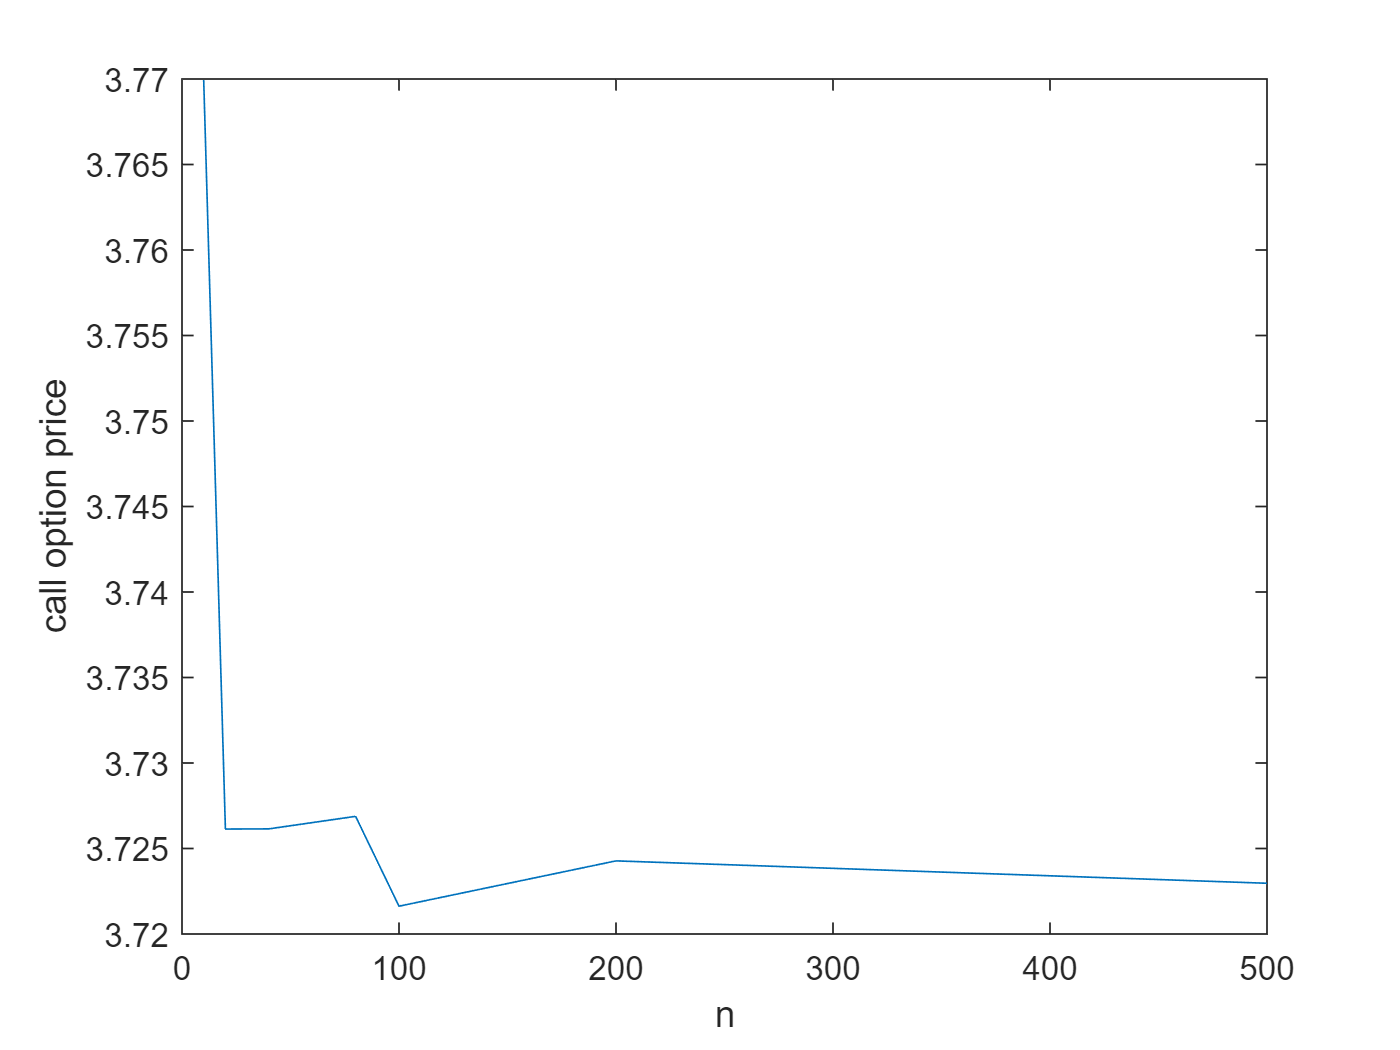

r = 0.05; sigma = 0.24; S0=32; T=0.5;
K=30; n_vec=[10,20,40,80,100,200,500];

Fast_callprice=@(n) call_price_a(n,T,S0,K,r,sigma);
call_values = arrayfun(@(tn) Fast_callprice(tn) , n_vec);

plot(n_vec,call_values)
xlabel("n")
ylabel("call option price")

(b) Use the binomial method in which 


$$u=e^{r\Delta } \left(1+\sqrt{e^{\sigma^2 \Delta } -1}\right),d=e^{r\Delta } \left(1-\sqrt{e^{\sigma^2 \Delta } -1}\right),p=\frac{1}{2}$$


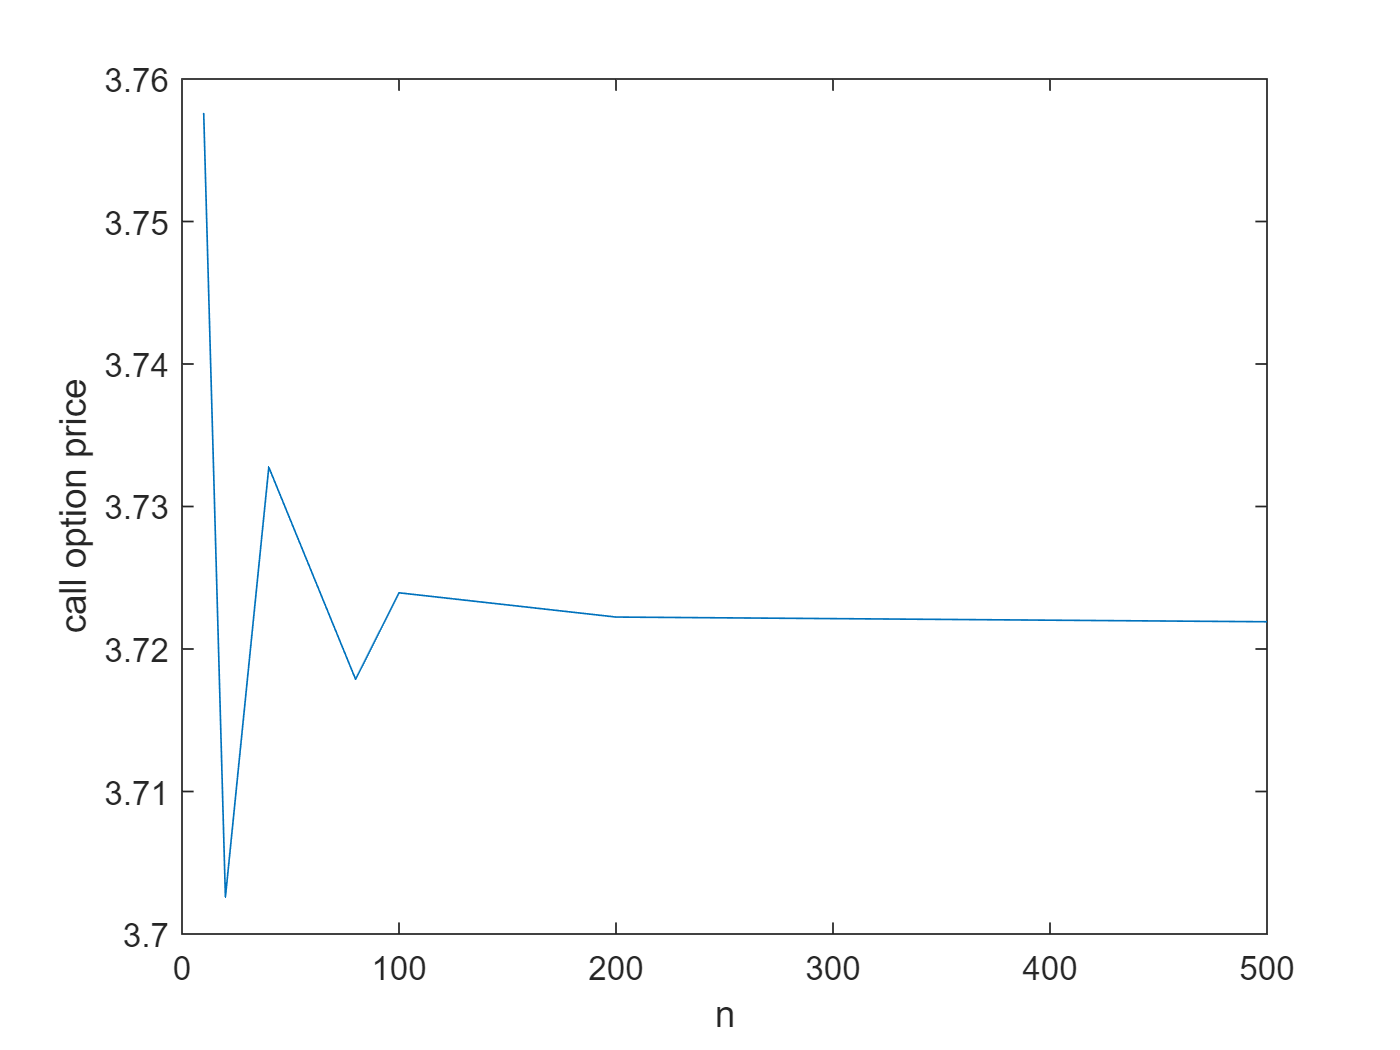

Fast_callprice=@(n) call_price_b(n,T,S0,K,r,sigma);
call_values_b = arrayfun(@(tn) Fast_callprice(tn) , n_vec);

plot(n_vec,call_values_b)
xlabel("n")
ylabel("call option price")

(c) Use the binomial method in which


$$u=e^{\left(r-\frac{\sigma^2 }{2}\right)\Delta +\sigma \sqrt{\Delta }} ,d=e^{\left(r-\frac{\sigma^2 }{2}\right)\Delta -\sigma \sqrt{\Delta }} ,p=\frac{1}{2}$$


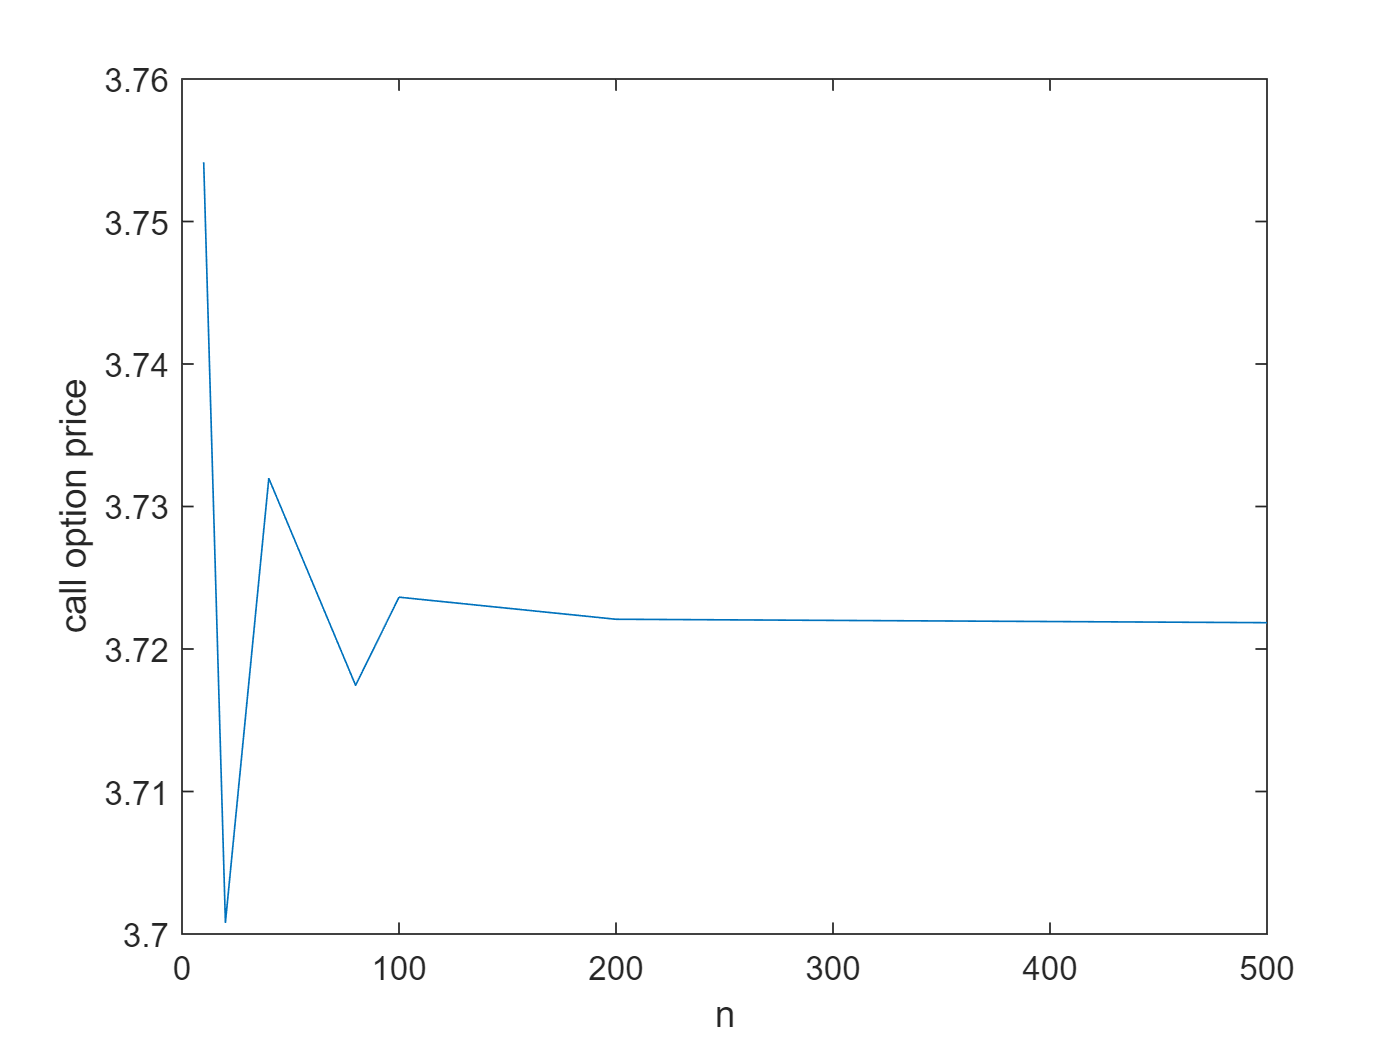

Fast_callprice=@(n) call_price_c(n,T,S0,K,r,sigma);
call_values_c = arrayfun(@(tn) Fast_callprice(tn) , n_vec);

plot(n_vec,call_values_c)
xlabel("n")
ylabel("call option price")

(d) Use the binomial method in which


$$u=e^{\sigma \sqrt{\Delta }} ,d=e^{-\sigma \sqrt{\Delta }} ,p=\frac{1}{2}+\frac{1}{2}\left(\frac{\left(r-\frac{\sigma^2 }{2}\right)\sqrt{\Delta }}{\sigma }\right)$$


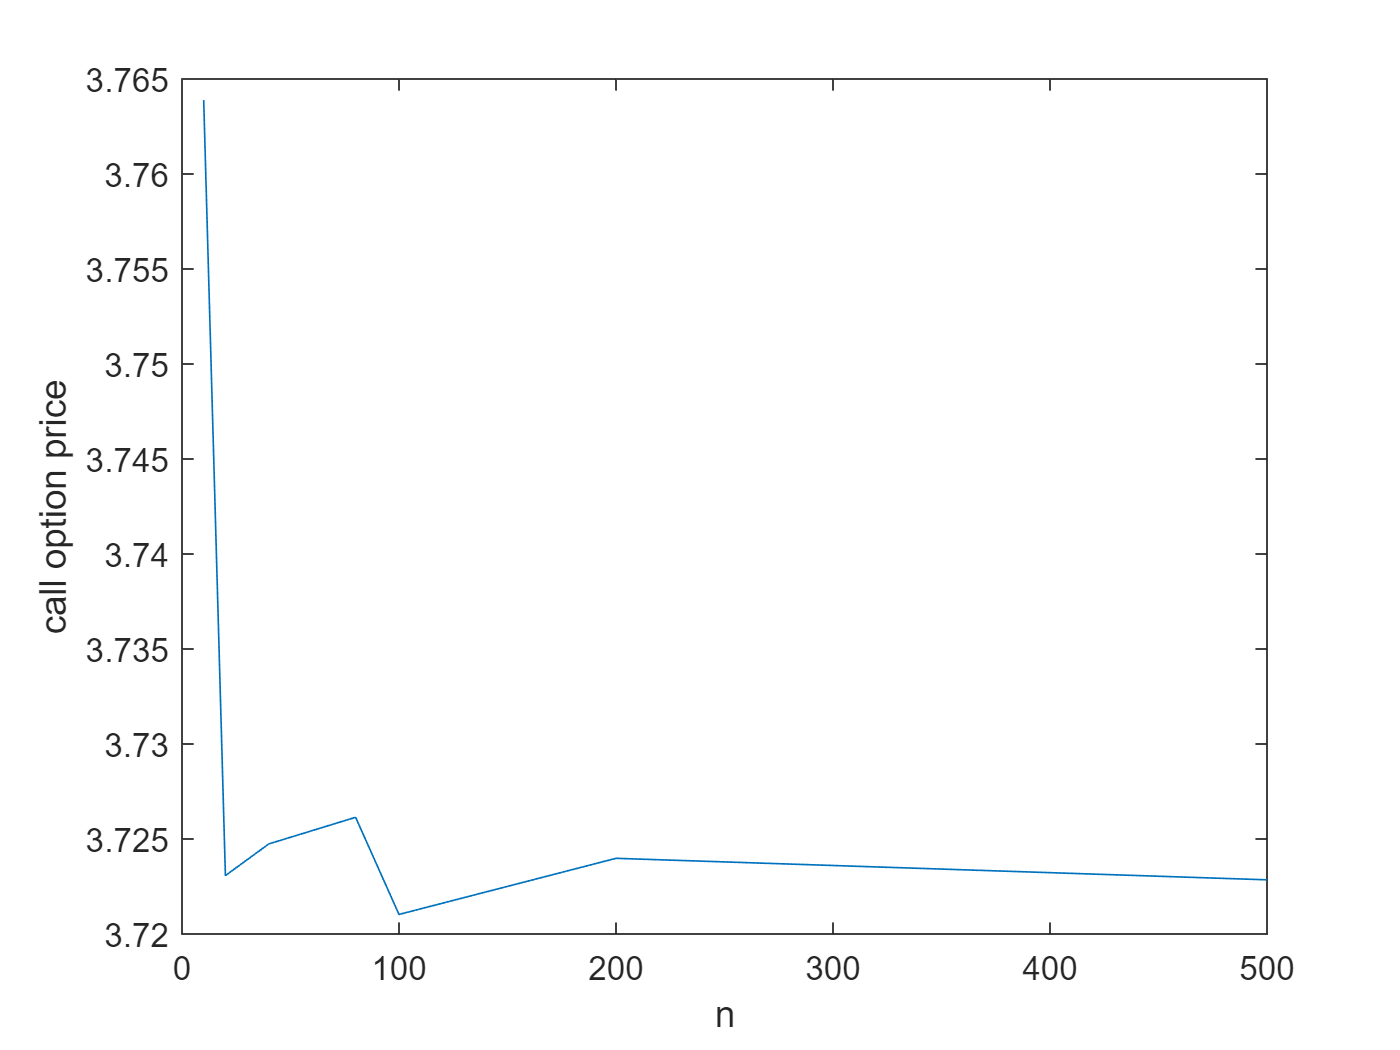

Fast_callprice=@(n) call_price_d(n,T,S0,K,r,sigma);
call_values_d = arrayfun(@(tn) Fast_callprice(tn) , n_vec);

plot(n_vec,call_values_d)
xlabel("n")
ylabel("call option price")

**2. Take the current price of AMZN. Use risk-free rate of 1% per annum, and a strike price that is the closest  integer to 110% of the current price (divisible by 50). Estimate the price of the American Call option that expires in January of next year, using the Binomial Method. AMZN does not pay dividends. To estimate the historical volatility, use 60 months of historical stock price data on the company. You may use  Bloomberg or finance.yahoo.com to obtain historical prices and the current stock price of AMZN. **

(a) Compare your estimated option price with the one you can get from Bloomberg or finance.yahoo.com and comment. 

initDate = '28-April-2017';
symbol = 'AMZN';
amzn_yahoo_raw = getMarketDataViaYahoo(symbol, initDate);
P = amzn_yahoo_raw{:,6}; % price of Amazon
sigma = std(diff(P)./P(1:length(P)-1))*sqrt(252)

sigma = 0.3215

r = 0.01;
S0 = amzn_yahoo_raw{height(amzn_yahoo_raw),6};
K = floor(S0*1.1/50)*50

K = 2700

T = 3/4; % assume it expires at the beginning if January
n = 500;
dt = T/n;
u = exp(sigma*sqrt(dt));
d = 1/u;
p = (exp(r*dt)-d)/(u-d);
% stock price record
stock_values = zeros(n+1);
stock_values(1,1) = S0;
for i = 2:(n+1)
    stock_values(1,i) = stock_values(1,i-1)*u;
    for j = 2:(i+1)
        stock_values(j,i) = stock_values(j-1,i-1)*d;
    end
end
option_values = zeros(n+1);
for j = 1:(n+1)
    option_values(j,n+1) = max([0, stock_values(j,n+1)-K]);
end
for i = n:-1:1
    for j = 1:i
        option_values(j,i) = max([0, stock_values(j,i)-K, exp(-r*dt)*(p*option_values(j,i+1)+(1-p)*option_values(j+1,i+1))]);
    end
end
% price of the American Call Option
option_values(1,1)

ans = 201.1989

The K I use is 2700. The final call option price is 199.3769. However, the actual price of the call option expiring in January 20 in Yahoo Finance is $239. The price I computed is less that the market price. 

(b) If the two prices in part (a) are different, then find the volatility that would make your estimated price equal to the market price. Comment on your finding (market’s expectation) by comparing the  historical volatility with the implied volatility. Outputs: Writeup: comments for parts (a) and (b). 

% implied volatility
iv = blsimpv(S0,K,r,T,239)

iv = 0.3657

The implied volatility (0.3681) is larger than the historical volatility (0.3216). So, the call option price using historical volatility is smaller than that using implied volatility.

**3. Consider the following information on the stock of a company and options on it: **$S_0$** = $49, X= $50, r = 0.03, **$\sigma$** = 0.2, T = 0.3846 (20 weeks), **$\mu$** = 0.14. Using the Binomial Method (any one of the parameter choices) estimate the following and draw the  graphs:** 

(i) Delta of the call option as a function of $S_0$, for $S_0$ ranging from $20 to $80, in increments of $2. 

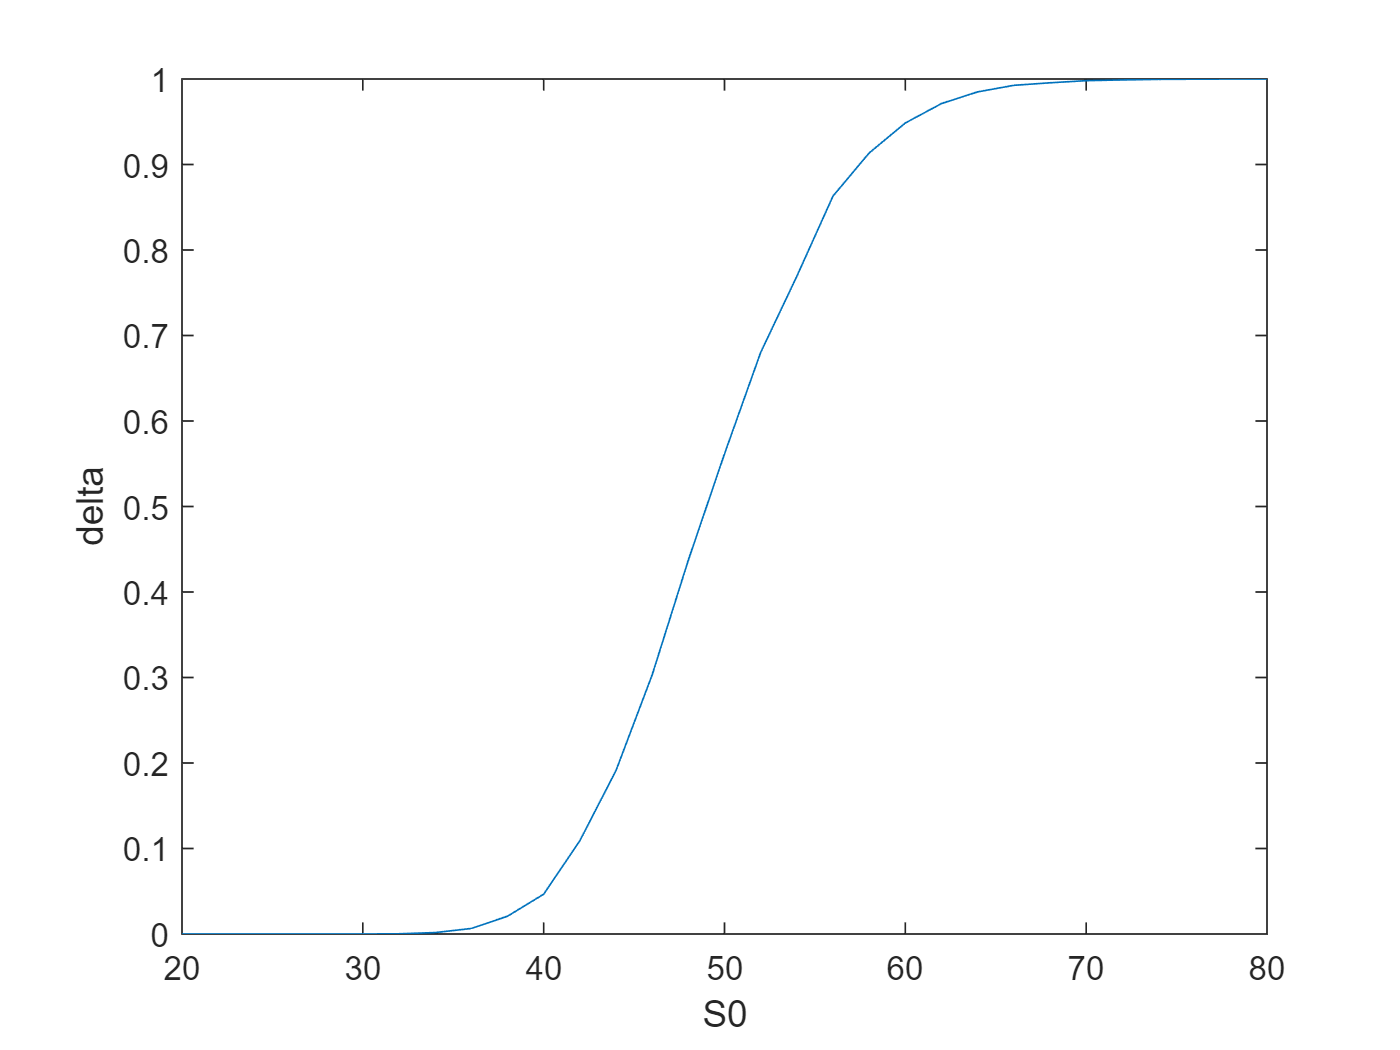

X=50; mu = 0.14;
r = 0.03; sigma = 0.2; T =0.3846;
epsilon = 0.001;
% delta = change of option price / change of price
S0_vec=20:2:80; 
Fast_callprice=@(Sx) call_price3(500,T,Sx,X,r,sigma);
delta_vec = arrayfun(@(tSx) (Fast_callprice(tSx+epsilon)-Fast_callprice(tSx-epsilon))/(2*epsilon), S0_vec);

plot(S0_vec,delta_vec)
xlabel("S0")
ylabel("delta")

(ii) Delta of the call option, as a function of T (time to expiration), from 0 to 0.3846 in increments of  0.01.  

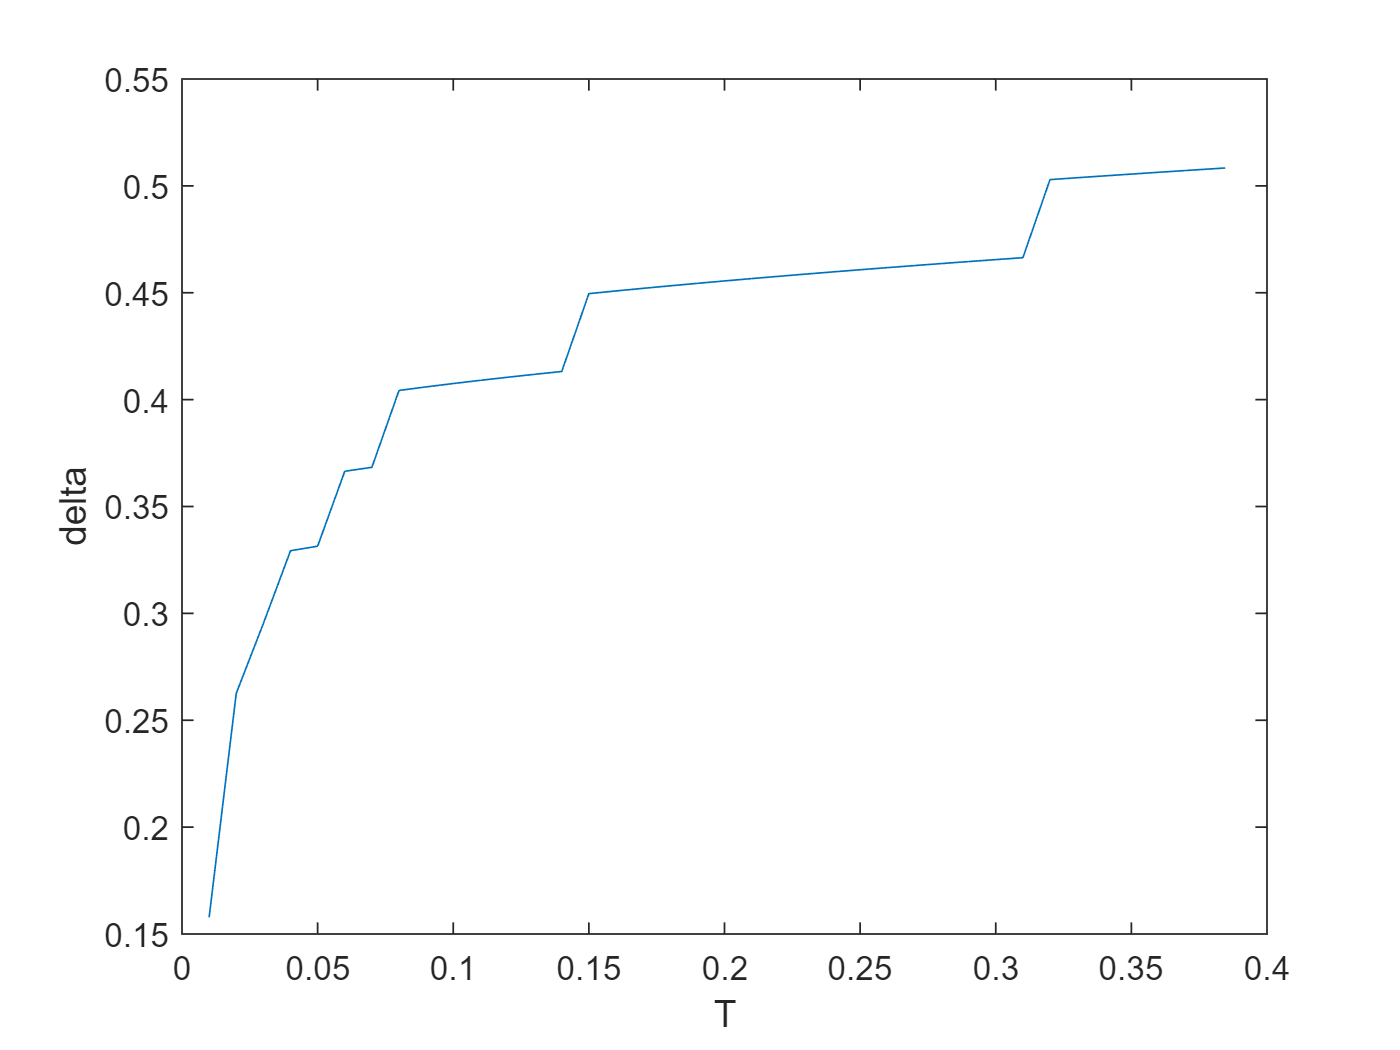

% delta = change of option price / change of price
S0 = 49;
T_vec = [0:0.01:0.3846,0.3846];
Fast_callprice=@(Tx) (call_price3(500,Tx,S0+epsilon,X,r,sigma)-call_price3(500,Tx,S0-epsilon,X,r,sigma))/(2*epsilon);
delta_vec2 = arrayfun(@(tTx) Fast_callprice(tTx), T_vec);

plot(T_vec,delta_vec2)
xlabel("T")
ylabel("delta")

(iii) Theta of the call option, as a function of $S_0$, for $S_0$ ranging from $20 to $80 in increments of $2. 

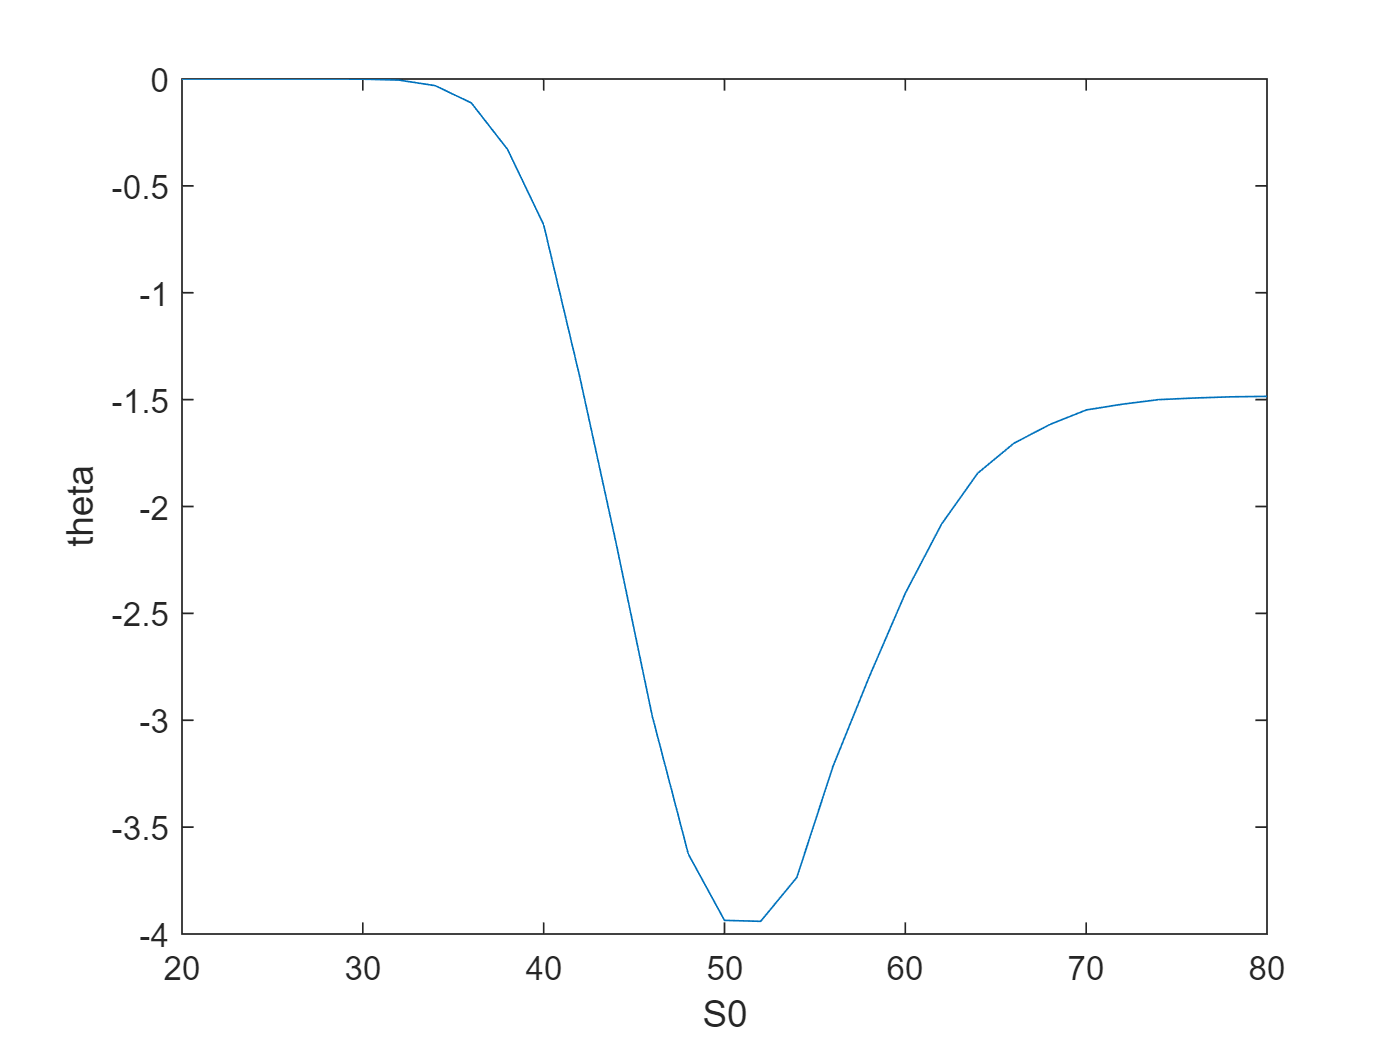

% Theta = change of option price / change of time to maturity
epsilon=0.004; 
Fast_callprice=@(Sx) (call_price3(500,T-epsilon,Sx,X,r,sigma)-call_price3(500,T+epsilon,Sx,X,r,sigma))/(2*epsilon);
theta_vec = arrayfun(@(tSx) Fast_callprice(tSx), S0_vec);

plot(S0_vec,theta_vec)
xlabel("S0")
ylabel("theta")

(iv) Gamma of the call option, as a function of $S_0$, for $S_0$ ranging from $20 to $80 in increments of $2.

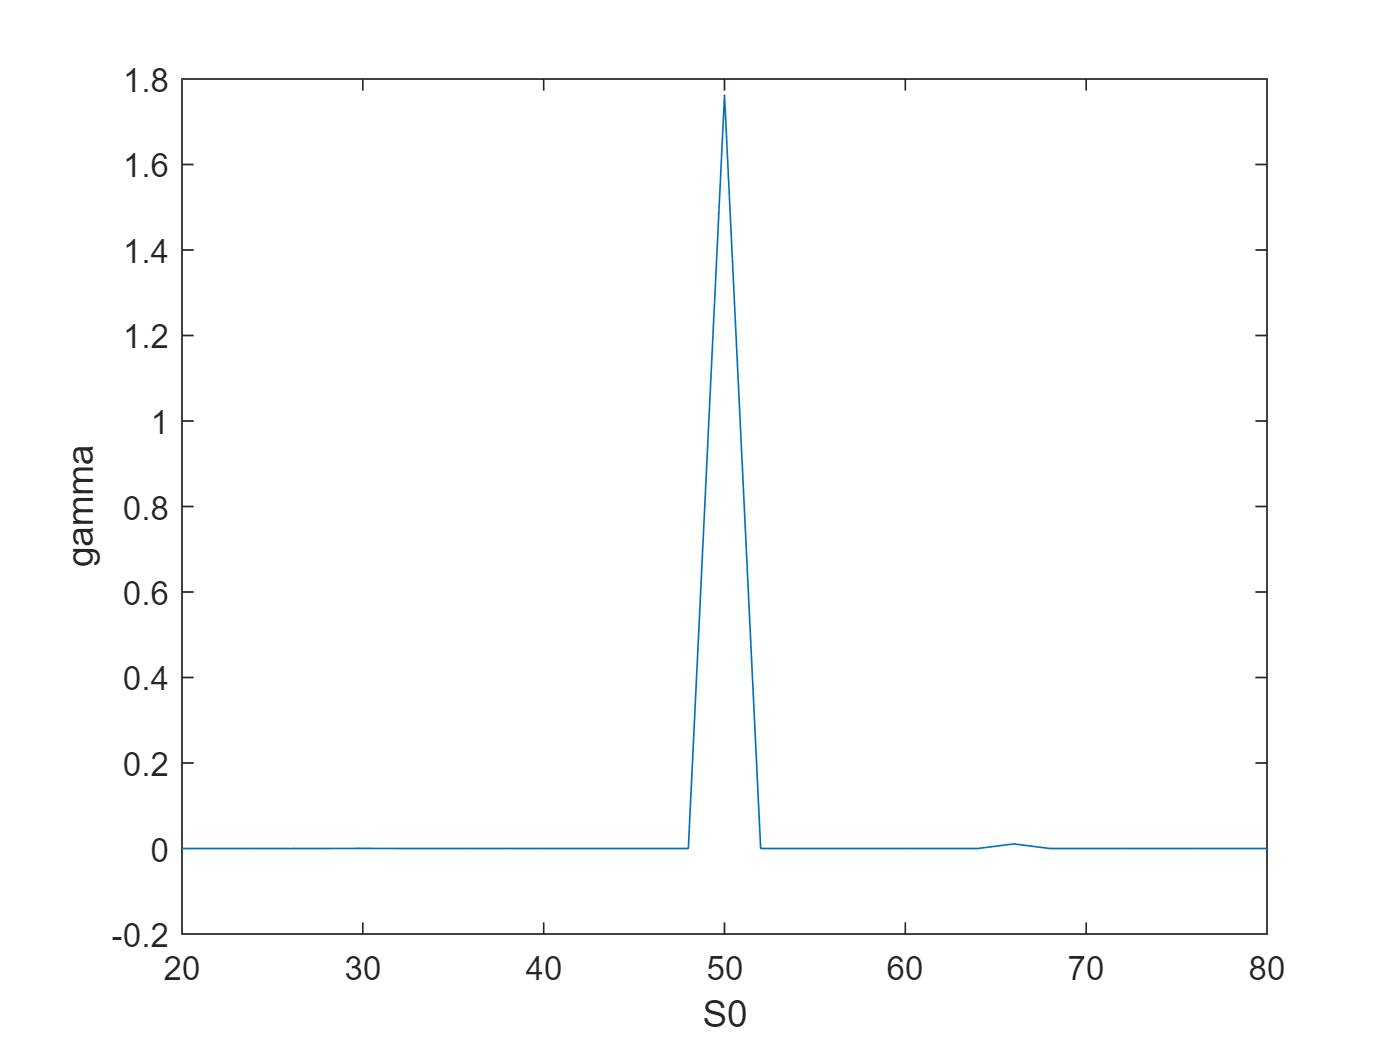

% Gamma = change of delta / change of price
epsilon=0.01;
Fast_gamma=@(Sx) (((call_price3(500,T,Sx+2*epsilon,X,r,sigma)-call_price3(500,T,Sx+epsilon,X,r,sigma))/epsilon ...
    -(call_price3(500,T,Sx-epsilon,X,r,sigma)-call_price3(500,T,Sx-2*epsilon,X,r,sigma))/epsilon)/(2*epsilon));
gamma_vec = arrayfun(@(tSx) Fast_gamma(tSx), S0_vec);

plot(S0_vec,gamma_vec)
xlabel("S0")
ylabel("gamma")

 (v) Vega of the call option, as a function of $S_0$, for $S_0$ ranging from $20 to $80 in increments of $2.

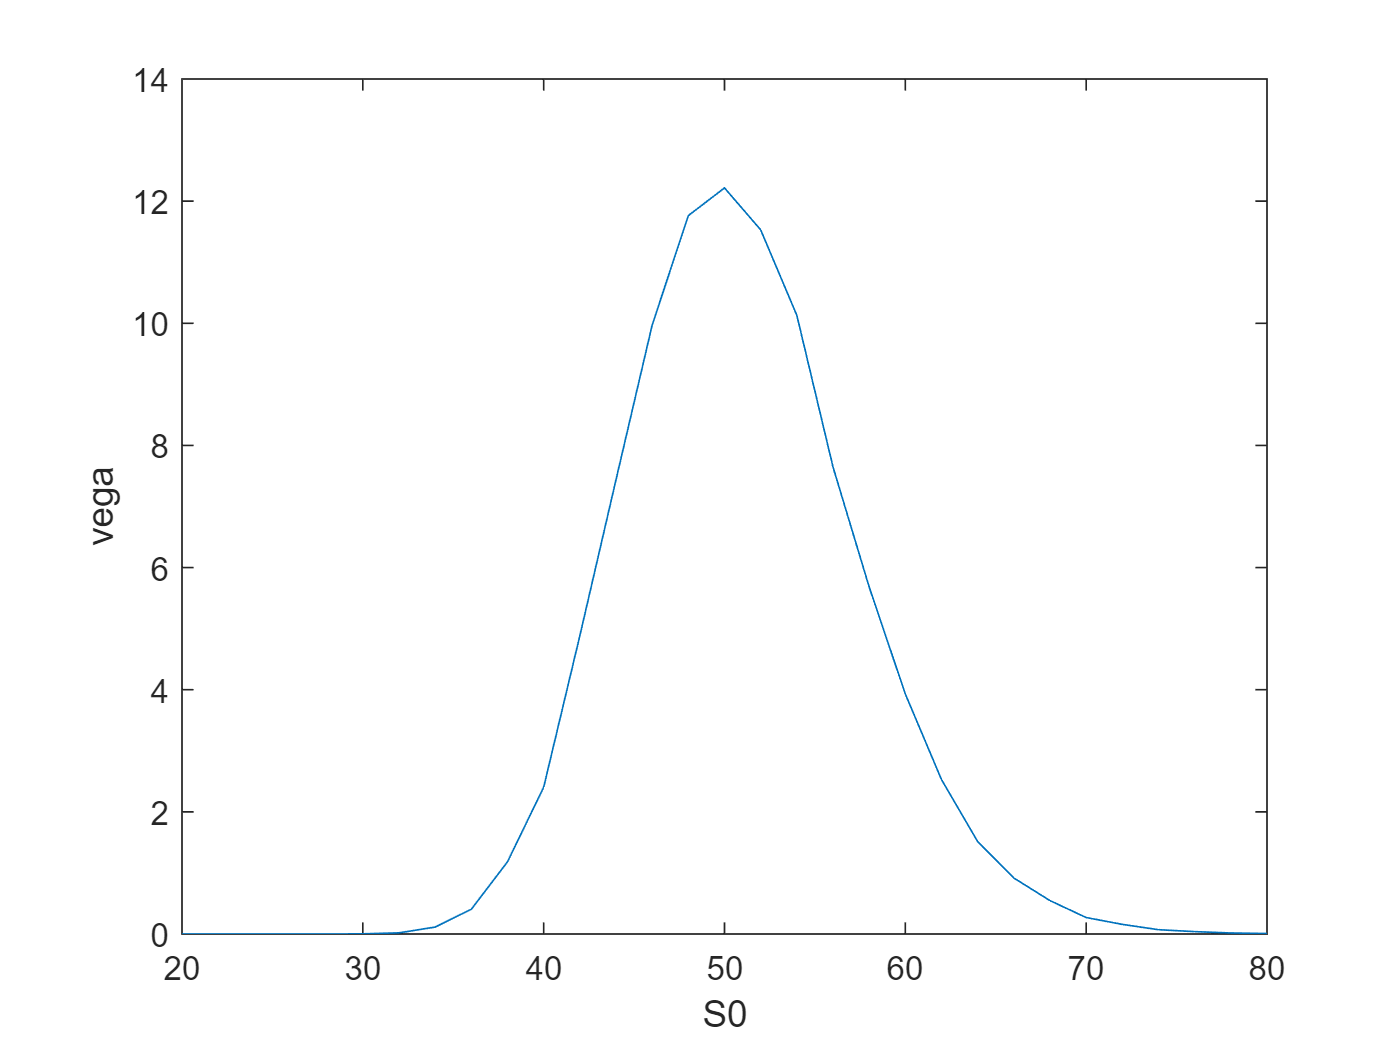

% vega = change of delta / change of sigma
epsilon=0.001;
Fast_vega=@(Sx) (call_price3(500,T,Sx,X,r,sigma+epsilon)-call_price3(500,T,Sx,X,r,sigma-epsilon))/(2*epsilon);
vega_vec = arrayfun(@(tSx) Fast_vega(tSx), S0_vec);

plot(S0_vec,vega_vec)
xlabel("S0")
ylabel("vega")

(vi) Rho of the call option, as a function of $S_0$, for $S_0$ ranging from $20 to $80 in increments of $2.

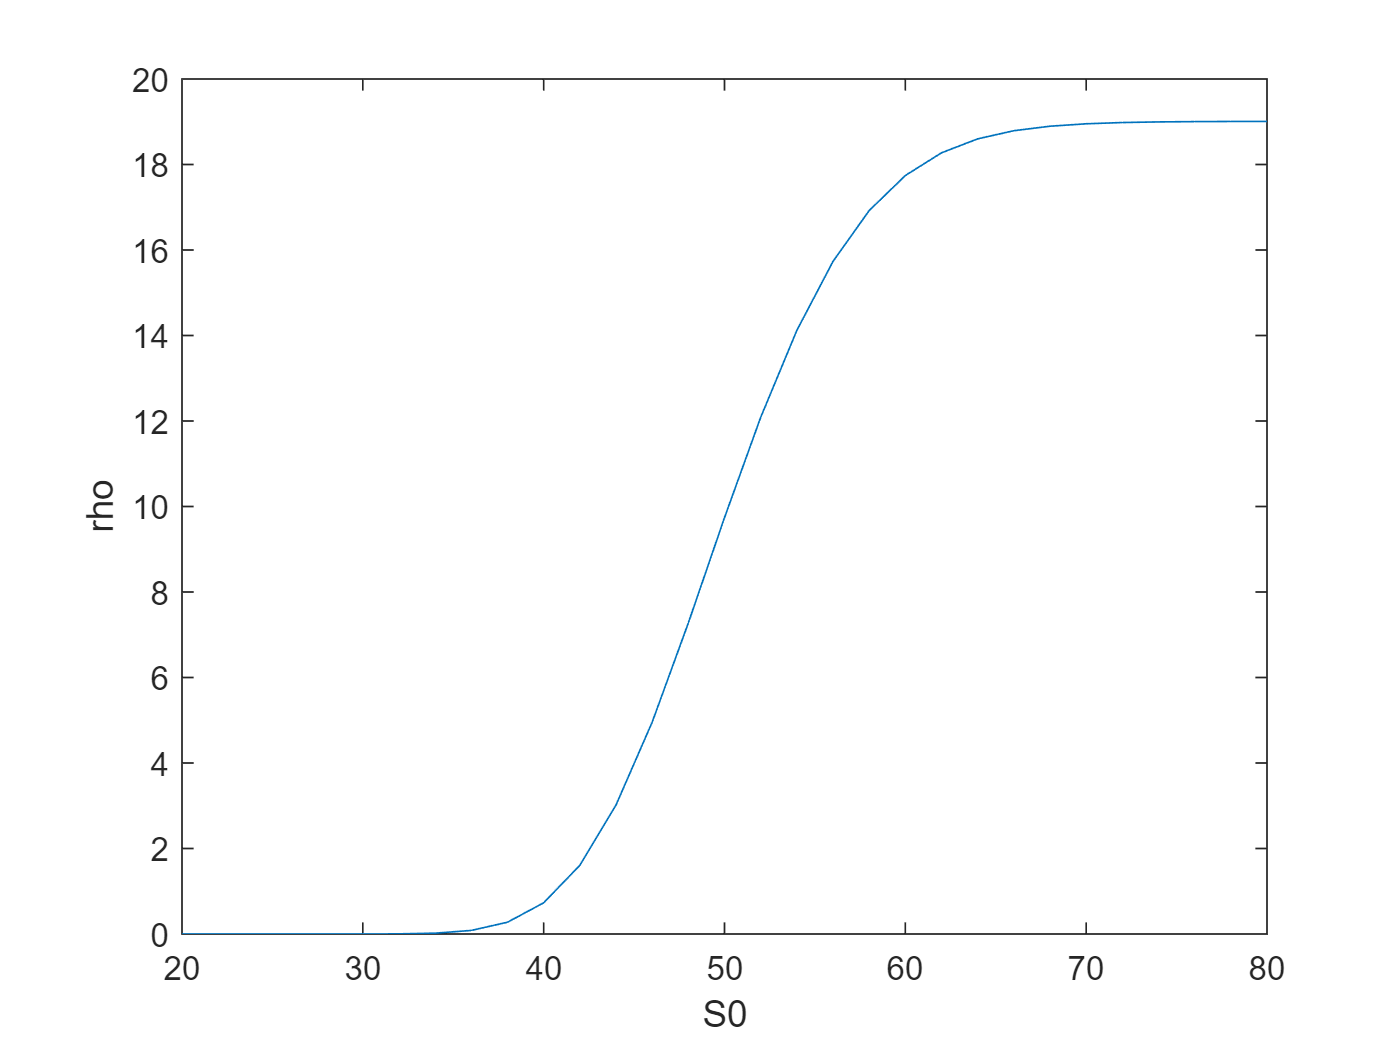

% rho = change of delta / change of risk free rate
epsilon=0.001;
Fast_rho=@(Sx) (call_price3(500,T,Sx,X,r+epsilon,sigma)-call_price3(500,T,Sx,X,r-epsilon,sigma))/(2*epsilon);
rho_vec = arrayfun(@(tSx) Fast_rho(tSx), S0_vec);

plot(S0_vec,rho_vec)
xlabel("S0")
ylabel("rho")

**4. Consider 12-month put options on a stock of company XYZ. Assume the risk-free rate is 5%/annum, the  volatility of the stock price is 30 % /annum, and the strike price of the option is $100. Use a Binomial Method to estimate the prices of European and American Put options with current stock prices varying  from $80 to $120 in increments of $4. Draw them all in one graph, compare them and comment on your findings. Outputs: i. Graphs: plot in a graph, and ii. writeup: comments. **

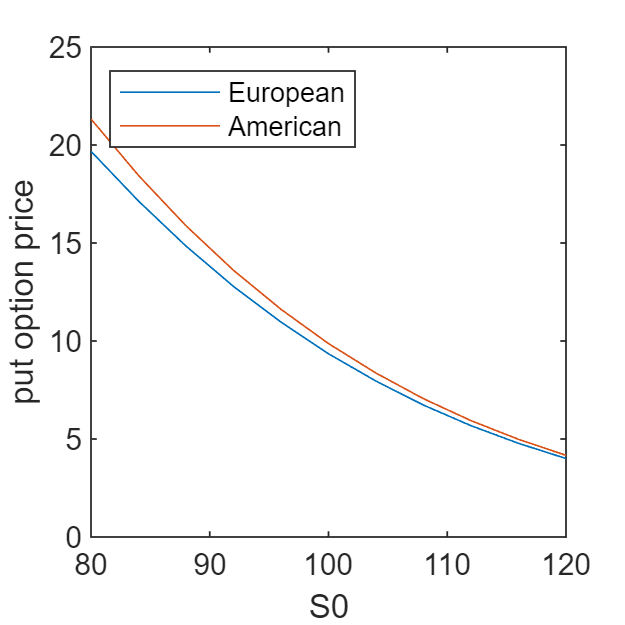

% put option
r = 0.05; sigma = 0.3; K=100; T=1;
S0_vec = 80:4:120;

Fast_put_euro=@(Sx) put_price4(500,T,Sx,K,r,sigma);
put_price_vec = arrayfun(@(tSx) Fast_put_euro(tSx), S0_vec);

Fast_put_am=@(Sx) put_price4_am(500,T,Sx,K,r,sigma);
put_price_vec_am = arrayfun(@(tSx) Fast_put_am(tSx), S0_vec);

plot(S0_vec,put_price_vec)
hold on
plot(S0_vec,put_price_vec_am)
hold off
set(gcf,'Position',[250 250 250 250])
legend(["European","American"],...
    'Location','northwest','NumColumns',1)
xlabel("S0")
ylabel("put option price")

Generally, the price of the Europea option is less than the price of the American option. As the current price increas, the put option price is lower.

**5. Compare the convergence rates of the two methods, (a) and (b) described below, by doing the following: Use the Trinomial Method to price a 6-month European Call option with the following information: the  risk-free interest rate is 5% per annum, the volatility is 24%/annum, the current stock price is $32, and the strike price is $30.** 

Divide the time interval into 𝑛 equal parts to estimate the price of this option. Use n = 10, 15, 20, 40, 70,  80, 100, 200 and 500 to estimate the price and draw them all in one graph, where the horizontal axis measures 𝑛, and the vertical one measures the price of the option. The two methods are in (a) and (b) below: 

(a) Use the trinomial method applied to the stock price-process ($S_t$ ) in which 


$$u=\frac{1}{d},d=e^{-\sigma \sqrt{3\Delta }} ,p_u =\frac{r\Delta \left(1-u\right)+{\left(r\Delta \right)}^2 +\sigma^2 \Delta }{\left(u-d\right)\left(1-d\right)},p_d =\frac{r\Delta \left(1-d\right)+{\left(r\Delta \right)}^2 +\sigma^2 \Delta }{\left(u-d\right)\left(u-1\right)},p_m =1-p_u -p_d$$


T = 0.5; S0 = 32; K = 30; r = 0.05; sigma = 0.24;
n_vec = [10,15,20,40,70,80,100,200,500];

Fast_callprice=@(n) call_price5_a(n,T,S0,K,r,sigma);
call_values5a = arrayfun(@(tn) Fast_callprice(tn), n_vec);

(b) Use the trinomial method applied to the Log-stock price-process ($X_t$ ) in which


$$\Delta X_u =\sigma \sqrt{3\Delta },d=-\sigma \sqrt{3\Delta },p_u =\frac{1}{2}\left(\frac{\sigma^2 \Delta +{\left(r-\frac{\sigma^2 }{2}\right)}^2 \Delta^2 }{{\Delta X_u }^2 }-\frac{\left(r-\frac{\sigma^2 }{2}\right)\Delta }{\Delta X_u }\right),p_d =\frac{1}{2}\left(\frac{\sigma^2 \Delta +{\left(r-\frac{\sigma^2 }{2}\right)}^2 \Delta^2 }{{\Delta X_u }^2 }+\frac{\left(r-\frac{\sigma^2 }{2}\right)\Delta }{\Delta X_u }\right),p_m =1-p_u -p_d$$


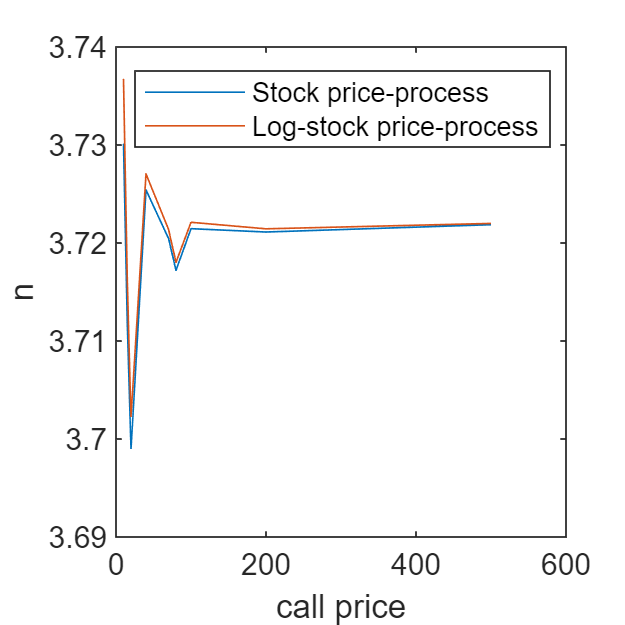

Fast_callprice=@(n) call_price5_b(n,T,S0,K,r,sigma);
call_values5b = arrayfun(@(tn) Fast_callprice(tn), n_vec);

plot(n_vec,call_values5a)
hold on
plot(n_vec,call_values5b)
hold off
set(gcf,'Position',[250 250 250 250])
legend(["Stock price-process","Log-stock price-process"],...
    'Location','northwest','NumColumns',1)
xlabel("call price")
ylabel("n")

As shown above, the convergence rate of the log-stock price-procss is higher than that of the stock price-procss.

**6. Use Halton’s Low-Discrepancy Sequences to price European Call options.  The code should be generic: it will prompt the user to input **$S_0$**, X, T, r, **$\sigma$**, N (number of points), **$b_1$** (base  1) and **$b_2$** (base 2). **Use the Box-Muller method to generate Standard Normal variates as follows: 


$$\left\lbrace \begin{array}{ll}
Z_1  & =\sqrt{-2\ln \left(H_1 \right)}\cos \left(2\pi H_2 \right)\\
Z_2  & =\sqrt{-2\ln \left(H_1 \right)}\sin \left(2\pi H_2 \right)
\end{array}\right.$$


 where 𝐻1 and 𝐻2 will be the Halton’s numbers with base $b_1$ and base $b_2$ respectively. 

For the call option price you may use the following formula: 


$$C=\mathit{\mathbf{E}}$$

$$\left(W_T \right)$$

$$=e^{-\textrm{rT}}$$

$$\mathit{\mathbf{E}}$$

$$\left(\max \left(0,S_0 {\;e}^{\left(r-\frac{\sigma^2 }{2}\right)T+\sigma W_T } -X\right)\right)$$


Inputs: $S_0$, X, T, r, $\sigma$, N, $b_1$, $b_2$ 

Outputs: Values: C

N=1000;b1=2;b2=7;
H1 = GetHalton(N, b1); % generate one-demensional Halton sequence with 100 numbers base 1
H2 = GetHalton(N, b2); % generate one-demensional Halton sequence with 100 numbers base 2

Z1 = sqrt(-2*log(H1)).*cos(2*pi*H2);
Z2 = sqrt(-2*log(H1)).*sin(2*pi*H2);
S0=32;X=30;T=0.5;r=0.05;sigma=0.24;
Wt = [Z1', Z2']*sqrt(T);
St = S0*exp((r-sigma^2/2)*T+sigma*Wt);
% call option price
C = exp(-r*T) * mean(max(0,St-X))

C = 3.7255

function call_value = call_price_a(n,T,S0,K,r,sigma)
    dt = T/n;
    c = (exp(-r*dt)+exp((r+sigma^2)*dt))/2;
    d = c-sqrt(c^2-1);
    u = 1/d;
    p = (exp(r*dt)-d)/(u-d);
    call_value = binomial_call(n,p,u,d,S0,K,T,r);
end

function call_value = call_price_b(n,T,S0,K,r,sigma)
    dt = T/n;
    d = exp(r*dt)*(1-sqrt(exp((sigma^2)*dt)-1));
    u = exp(r*dt)*(1+sqrt(exp((sigma^2)*dt)-1));
    p = 1/2;
    call_value = binomial_call(n,p,u,d,S0,K,T,r);
end

function call_value = call_price_c(n,T,S0,K,r,sigma)
    dt = T/n;
    u = exp((r-(sigma^2)/2)*dt+sigma*sqrt(dt));
    d = exp((r-(sigma^2)/2)*dt-sigma*sqrt(dt));
    p = 1/2;
    call_value = binomial_call(n,p,u,d,S0,K,T,r);
end

function call_value = call_price_d(n,T,S0,K,r,sigma)
    dt = T/n;
    u = exp(sigma*sqrt(dt));
    d = 1/u;
    p = 1/2+1/2*((r-(sigma^2)/2)*sqrt(dt)/sigma);
    call_value = binomial_call(n,p,u,d,S0,K,T,r);
end

function call_value = call_price3(n,T,S0,K,r,sigma)
    dt = T/n;
    u = exp(sigma*sqrt(dt));
    d = 1/u;
    p = (exp(r*dt)-d)/(u-d);
    call_value = binomial_call(n,p,u,d,S0,K,T,r);
end

function call_value = binomial_call(n,p,u,d,S0,K,T,r)
    % trinomial method for call
    call_value = 0;
    for t = 0:n
        prob = nchoosek(n,t)*(p^t)*((1-p)^(n-t));
        St = S0 * (u^t)*(d^(n-t));
        call_value = call_value + max(St-K,0) * prob;
    end
    call_value = call_value*exp(-r*T);
end

function put_value = put_price4(n,T,S0,K,r,sigma)
    dt = T/n;
    u = exp(sigma*sqrt(dt));
    d = 1/u;
    p = (exp(r*dt)-d)/(u-d);
    put_value = binomial_put(n,p,u,d,S0,K,T,r);
end

function put_value = binomial_put(n,p,u,d,S0,K,T,r)
    % trinomial method for put
    put_value = 0;
    for t = 0:n
        prob = nchoosek(n,t)*(p^t)*((1-p)^(n-t));
        St = S0 * (u^t)*(d^(n-t));
        put_value = put_value + max(K-St,0) * prob;
    end
    put_value = put_value*exp(-r*T);
end

function put_value = put_price4_am(n,T,S0,K,r,sigma)
    dt = T/n;
    u = exp(sigma*sqrt(dt));
    d = 1/u;
    p = (exp(r*dt)-d)/(u-d);
    % stock price record
    stock_values = zeros(n+1);
    stock_values(1,1) = S0;
    for i = 2:(n+1)
        stock_values(1,i) = stock_values(1,i-1)*u;
        for j = 2:(i+1)
            stock_values(j,i) = stock_values(j-1,i-1)*d;
        end
    end
    option_values = zeros(n+1);
    for j = 1:(n+1)
        option_values(j,n+1) = max([0, K-stock_values(j,n+1)]);
    end
    for i = n:-1:1
        for j = 1:i
            option_values(j,i) = max([0, K-stock_values(j,i), exp(-r*dt)*(p*option_values(j,i+1)+(1-p)*option_values(j+1,i+1))]);
        end
    end
    % price of the American Call Option
    put_value = option_values(1,1);
end

function call_value = call_price5_a(n,T,S0,K,r,sigma)
    % trinomial method applied to the stock price-process
    dt = T/n;
    d = exp(-sigma*sqrt(3*dt));
    u = 1/d;
    p_d = (r*dt*(1-u)+(r*dt)^2+sigma^2*dt)/((u-d)*(1-d));
    p_u = (r*dt*(1-d)+(r*dt)^2+sigma^2*dt)/((u-d)*(u-1));
    call_value = trinomial_call(n,p_u,p_d,u,d,S0,K,T,r);
end

function call_value = call_price5_b(n,T,S0,K,r,sigma)
    % trinomial method applied to the Log-stock price-process
    dt = T/n;
    dxu = sigma*sqrt(3*dt);
    dxd = -dxu;
    u = exp(dxu);
    d = exp(dxd);
    part1 = ((sigma^2)*dt + (r-(sigma^2)/2)^2*dt^2)/(dxu^2);
    part2 = (r-(sigma^2)/2)*dt/dxu;
    p_d = 1/2 * (part1-part2);
    p_u = 1/2 * (part1+part2);

    call_value = trinomial_call(n,p_u,p_d,u,d,S0,K,T,r);
end

function call_value = trinomial_call(n,p_u,p_d,u,d,S0,K,T,r)
    % trinomial method for call
    call_value = 0;
    p_m = 1-p_u-p_d;
    for t = 0:n
        for x = 0:(n-t)
            prob = nchoosek(n,t)*(p_u^t)*nchoosek(n-t,x)*(p_d^x)*(p_m^(n-t-x));
            St = S0 * (u^t)*(d^x);
            call_value = call_value + max(St-K,0) * prob;
        end
    end
    call_value = call_value*exp(-r*T);
end

function Seq = GetHalton(HowMany, Base)
    % generate one demensional Helton Sequence
    % note: adopted from Brandimartets "Numerical methods in finance and economics: a MATLAB-based introduction"
    Seq = zeros(HowMany,1);
    % NumBits = m+1
    % m^r <= HowMany < m^(r+1) So, r <= log(HowMany)/log(Base) < r+1
    NumBits = 1+ceil(log(HowMany)/log(Base));
    VetBase = Base.^(-(1:NumBits));
    WorkVet = zeros(1,NumBits);
    for i=1:HowMany
        j=1;
        ok = 0; % ok is a flag
        while ok == 0
            WorkVet(j) = WorkVet(j)+1;
            if WorkVet(j) < Base
                ok = 1;
            else
                WorkVet(j) = 0;
                j = j+1;
            end
        end
        Seq(i) = dot(WorkVet,VetBase);
    end
end